% Specify the folder containing DAC data files
folderPath = 'ADC_data';

% Get a list of all files in the folder
files = dir(fullfile(folderPath, '*.csv'))

files = 16×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



% Loop through each file and load it into a cell array
allData = cell(numel(files), 1);
for i = 1:numel(files)
    filePath = fullfile(folderPath, files(i).name);
    allData{i} = readtable(filePath, "VariableNamingRule","preserve");
end



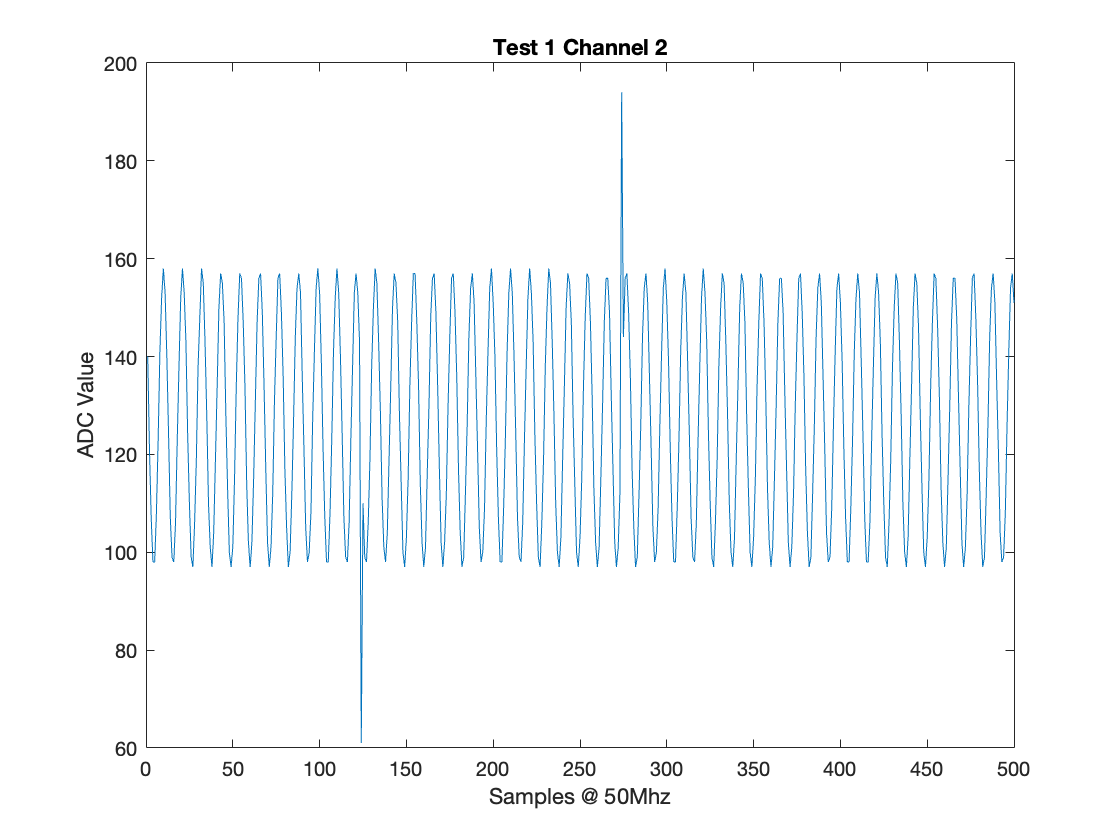

for i = 1:length(files)
    data = allTables{i};
    plot(data.("Bus"))
    xlabel("Samples @ 50Mhz")
    ylabel("ADC Value")
    title(['Test ', num2str(i), ' Channel 1'])
    plotFileName = fullfile("ADC_data_plots", ['plot_', num2str(i),'_channel1' ,'.png']);
    saveas(gcf, plotFileName);
    close(gcf);

    plot(data.("Bus2"))
    xlabel("Samples @ 50Mhz")
    ylabel("ADC Value")
    title(['Test ', num2str(i), ' Channel 2'])
    plotFileName = fullfile("ADC_data_plots", ['plot_', num2str(i),'_channel2' ,'.png']);
    saveas(gcf, plotFileName);
    close(gcf);

end